# Análise de Fourier

## Boas práticas

clear all;          %%% limpa todas as variáveis
close all;          %%% fecha todas as janelas
clc;                %%% limpa a tela


## Definindo o sinal de entrada

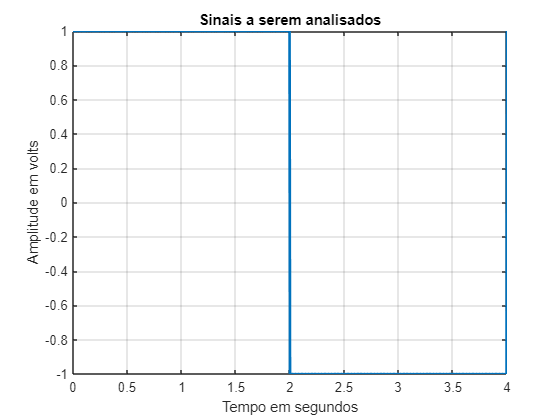

%%% Sinal #1 - onda quadrada no domínio do tempo
%%% Definindo o sinal g(t)

Ap = +1;        %%% amplitude positiva
An = -1;        %%% amplitude negativa

% Os principais tempos do sinal pulsado

t1 = 0;         %%% tempo inicial
t2 = +2;        %%% fim do ciclo positivo
t3 = +4;        %%% fim de um período do sinal

T0 = t3 - t1;   %%% período do sinal
Tp = t2 - t1;   %%% Duração do ciclo positivo
Tn = t3 - t2;   %%% Duração do ciclo negativo

dc = 100*Tp/T0; %%% duty cicle
w0 = 2*pi/T0;   %%% frequência angular

%%% Definindo os termos da série

ax  = @(n,w0,t)     cos(n*w0*t);
bx  = @(n,w0,t)     sin(n*w0*t);

%%% visualizar os sinais no mesmo gráfico

res = T0/1000;                  %%% resoluçao em pontos 
tmp = [0:res:T0];               %%% variável tempo
g_t = square(w0*tmp,dc);        %%% onda quadrada

figure(1)

plot(tmp,g_t,'LineWidth',2);                 %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Sinais a serem analisados');                  %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y

%%% Sinal #1 - onda quadrada no domínio da frequência


### Determinação dos termos da série de fourier


$$a_{n} = \frac{\int_{T_0}g(t)cos(n\; \omega_0 \; t)dt}{\int_{T_0}cos^2(n\; \omega_0 \; t)dt}
$$


%%%% Análise simbólica

syms Tp T0 Ap An w0 t n

%%% determinando o valor de a_n

num_a = int(Ap*cos(n*w0*t),t,t1,t2) +  int(An*cos(n*w0*t),t,t2,t3);
den_a = int(cos(n*w0*t)^2,t,0,T0);



$$b_{n} = \frac{\int_{T_0}g(t)sin(n\; \omega_0 \; t)dt}{\int_{T_0}sin^2(n\; \omega_0 \; t)dt}
$$



%%% determinando o valor de b_n

num_b = int(Ap*sin(n*w0*t),t,t1,t2) +  int(An*sin(n*w0*t),t,t2,t3);
den_b = int(sin(n*w0*t)^2,t,0,T0);

%%% Definindo o sinal g(t)

Ap = +1;        %%% amplitude positiva
An = -1;        %%% amplitude negativa

% Os principais tempos do sinal pulsado

t1 = 0;        %%% tempo inicial
t2 = +2;        %%% fim do ciclo positivo
t3 = +4;        %%% fim de um período do sinal

T0 = t3 - t1;   %%% período do sinal
Tp = t2 - t1;   %%% Duração do ciclo positivo
Tn = t3 - t2;   %%% Duração do ciclo negativo

dc = 100*Tp/T0; %%% duty cicle
w0 = 2*pi/T0;   %%% frequência angular

a_n = eval(num_a)/eval(den_a);
b_n = eval(num_b)/eval(den_b);

### Síntese de Fourier


$$g(t) = \sum_{n=1}^{\infty} a_n*cos(n\; \omega_0\; t) +  b_n*sin(n\; \omega_0\; t)$$


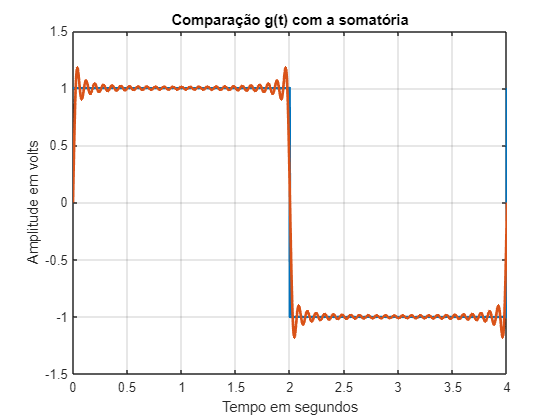

%%% Quantas harmônicas eu desejo somar?

N_harmonicas = 50;

%%% Variar o valor de n

n = [1:1:N_harmonicas];

%%% Determinar os valores numéricos de an e bn

an_num = eval(a_n);
bn_num = eval(b_n);

%%% Somar os termos an e bn --> g(t) --> síntese

aux =  0;                               %%% variável auxiliar para a somatória
res = T0/1000;                          %%% o passo de tempo é 1000 vezes 
                                          % menor que o período
t   =  [t1:res:t3];                     %%% variável tempo

for k=1:N_harmonicas

    aux = aux + an_num(k)*cos(n(k)*w0*t) + bn_num(k)*sin(n(k)*w0*t);

end

g_ts = aux;                   % copia o valor final do sinal g(t)

%%% Visualizar os valores de g(t) sobrepostos --> g(t) inicial e g(t)
%%% sintetizado

figure(2)

plot(tmp,g_t,tmp,g_ts,'LineWidth',2);                %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y

## Definindo o filtro

%%% Determinando o filtro

Gw = @(w,wc)  wc./(j*w + wc);

fc = 0.03   ;      %%% frequência de corte
wc = 2*pi*fc;      %%% frequência de corte em rd/s
w  = n*w0;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gw(w,wc); 



## Determinando o sinal de saída

%%% O sinal de saída é a entrada vezes o ganho
%%% Módulo

Yaw = abs(ganho).*an_num;
Ybw = abs(ganho).*bn_num;

%%% Fase

Fase = atan(imag(ganho)./real(ganho));


### Síntese de Fourier


$$g(t) = \sum_{n=1}^{\infty} a_n*cos(n\; \omega_0\; t) +  b_n*sin(n\; \omega_0\; t)$$


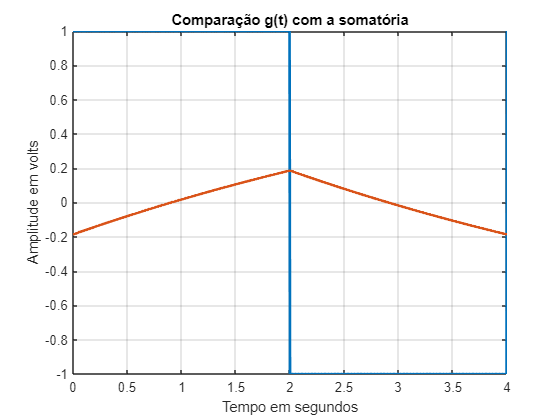

%%% Quantas harmônicas eu desejo somar?

N_harmonicas = 50;

%%% Variar o valor de n

n = [1:1:N_harmonicas];


%%% Somar os termos an e bn --> g(t) --> síntese

aux =  0;                               %%% variável auxiliar para a somatória
res = T0/1000;                          %%% o passo de tempo é 1000 vezes 
                                          % menor que o período
t   =  [t1:res:t3];                     %%% variável tempo

for k=1:N_harmonicas

    aux = aux + Yaw(k)*cos(n(k)*w0*t+Fase(k)) + Ybw(k)*sin(n(k)*w0*t+Fase(k));

end

y_ts = aux;                   % copia o valor final do sinal g(t)

%%% Visualizar os valores de g(t) sobrepostos --> g(t) inicial e g(t)
%%% sintetizado

figure(3)

plot(tmp,g_t,tmp,y_ts,'LineWidth',2);                %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y

## Visualizando os sinais no tempo e frequência

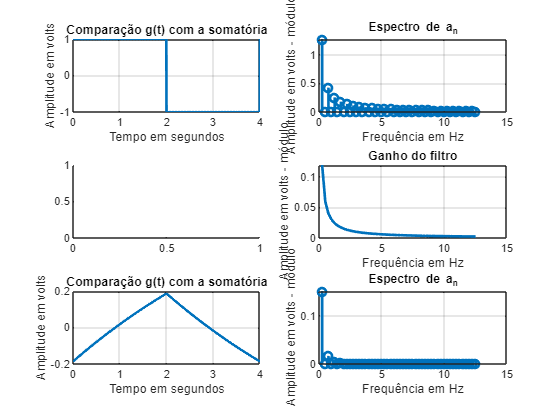


subplot(3,2,1)      %%% sinal de entrada
plot(tmp,g_t,'LineWidth',2);                         %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y
subplot(3,2,3)      %%% resposta do filtro


subplot(3,2,5)      %%% sinal de saída
plot(tmp,y_ts,'LineWidth',2);                %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y


%%%%% Fourier

subplot(3,2,2)      %%% sinal de entrada
stem(n*w0/(2*pi),sqrt(abs(an_num).^2 + abs(bn_num).^2),'LineWidth',2);         %%% plota o espectro de an
grid;                                                %%% cria um grid
title('Espectro de a_n');                            %%% título do gráfico
xlabel('Frequência em Hz');                          %%% Eixo x
ylabel('Amplitude em volts - módulo');               %%% Eixo y

subplot(3,2,4)      %%% resposta do filtro

plot(n*w0/(2*pi),abs(ganho) ,'LineWidth',2);         %%% plota o espectro de an
grid;                                                %%% cria um grid
title('Ganho do filtro');                            %%% título do gráfico
xlabel('Frequência em Hz');                          %%% Eixo x
ylabel('Amplitude em volts - módulo');               %%% Eixo y
subplot(3,2,4)      %%% resposta do filtro


subplot(3,2,6)      %%% sinal de saída
stem(n*w0/(2*pi),sqrt(abs(Yaw).^2 + abs(Ybw).^2),'LineWidth',2);         %%% plota o espectro de an
grid;                                                %%% cria um grid
title('Espectro de a_n');                            %%% título do gráfico
xlabel('Frequência em Hz');                          %%% Eixo x
ylabel('Amplitude em volts - módulo');               %%% Eixo y
subplot(3,2,4)      %%% resposta do filtro

## Analisando um sinal real

figure(5)
plot(data(1:100000,2))

Unrecognized function or variable 'data'.


sound(data(1:100000,2),fs)

data = data(1:100000,2);


### Fourier Guitarra

### Filtro passa baixa

Npontos = length(data);
frequencia = linspace(-fs/2,fs/2,Npontos);
Guitarra_w = fft(data(:,1));

figure(6)

stem(frequencia,fftshift(abs(Guitarra_w)))
%%% Aplicando um filtro

%%% Determinando o filtro

Gw = @(w,wc)  wc./(j*w + wc);

fc = 1000  ;                  %%% frequência de corte
wc = 2*pi*fc;                 %%% frequência de corte em rd/s
w  = 2*pi*frequencia;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gw(w,wc)'; 

%%% saída do filtro em frequência

Ys = ganho.*fftshift(Guitarra_w);

%%% saída do filtro no tempo

ys = ifft(Ys);

sound(real(ys),fs)

figure(7)

stem(frequencia,abs(Ys))

## Fourier da Gaita Blues

### Filtro Passa baixa

Npontos = length(data_blues);
frequencia = linspace(-fs_blues/2,fs_blues/2,Npontos);
Blues_w = fft(data_blues(:,1));

figure(6)

stem(frequencia,fftshift(abs(Blues_w)))
%%% Aplicando um filtro

%%% Determinando o filtro

Gw = @(w,wc)  wc./(j*w + wc);

fc = 5000  ;                  %%% frequência de corte
wc = 2*pi*fc;                 %%% frequência de corte em rd/s
w  = 2*pi*frequencia;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gw(w,wc)'; 

%%% saída do filtro em frequência

Ys = ganho.*fftshift(Blues_w);

%%% saída do filtro no tempo

ys = ifft(Ys);

sound(real(ys),fs)

figure(7)

stem(frequencia,abs(Ys))

### Passa alta e baixa

Npontos = length(data_blues);
frequencia = linspace(-fs_blues/2,fs_blues/2,Npontos);
Blues_w = fft(data_blues(:,1));

figure(6)

stem(frequencia,fftshift(abs(Blues_w)))

%%% Aplicando um filtro

%%% Determinando o filtro

Gwb = @(w, wcb)  wcb./(j*w + wcb);
Gwa = @(w, wca)  j*w./(j*w+wca);


fcb = 5000  ;                  %%% frequência de corte
wcb = 2*pi*fcb;                 %%% frequência de corte em rd/s
fca = 380  ;                  %%% frequência de corte
wca = 2*pi*fca;                 %%% frequência de corte em rd/s

w  = 2*pi*frequencia;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gwa(w,wca)'.*Gwb(w,wcb)'; 

%%% saída do filtro em frequência

Ys = ganho.*fftshift(Blues_w);

%%% saída do filtro no tempo

ys = ifft(Ys);

sound(real(ys),fs)

figure(7)

stem(frequencia,abs(Ys))

## Onda quadrada filtro

### Passa baixa

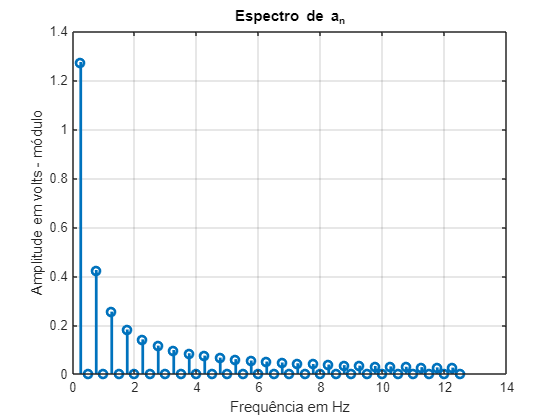

stem(n*w0/(2*pi),sqrt(abs(an_num).^2 + abs(bn_num).^2),'LineWidth',2);         %%% plota o espectro de an
grid;                                                %%% cria um grid
title('Espectro de a_n');                            %%% título do gráfico
xlabel('Frequência em Hz');                          %%% Eixo x
ylabel('Amplitude em volts - módulo');               %%% Eixo y

%%% Aplicando um filtro

%%% Determinando o filtro

Gw = @(w,wc)  wc./(j*w + wc);

fc = 2    ;                  %%% frequência de corte
wc = 2*pi*fc;                 %%% frequência de corte em rd/s
frequencia = 0.25*[1:1:N_harmonicas];
w  = 2*pi*frequencia;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gw(w,wc)

ganho =    0.9846 - 0.1231i   0.9412 - 0.2353i   0.8767 - 0.3288i   0.8000 - 0.4000i   0.7191 - 0.4494i   0.6400 - 0.4800i   0.5664 - 0.4956i   0.5000 - 0.5000i   0.4414 - 0.4966i   0.3902 - 0.4878i   0.3459 - 0.4757i   0.3077 - 0.4615i   0.2747 - 0.4464i   0.2462 - 0.4308i   0.2215 - 0.4152i   0.2000 - 0.4000i   0.1813 - 0.3853i   0.1649 - 0.3711i   0.1506 - 0.3576i   0.1379 - 0.3448i   0.1267 - 0.3327i   0.1168 - 0.3212i   0.1079 - 0.3103i   0.1000 - 0.3000i   0.0929 - 0.2903i   0.0865 - 0.2811i   0.0807 - 0.2724i   0.0755 - 0.2642i   0.0707 - 0.2564i   0.0664 - 0.2490i   0.0624 - 0.2420i   0.0588 - 0.2353i   0.0555 - 0.2290i   0.0525 - 0.2230i   0.0497 - 0.2172i   0.0471 - 0.2118i   0.0447 - 0.2066i   0.0424 - 0.2016i   0.0404 - 0.1968i   0.0385 - 0.1923i   0.0367 - 0.1880i   0.0350 - 0.1838i   0.0335 - 0.1798i   0.0320 - 0.1760i   0.0306 - 0.1723i   0.0294 - 0.1688i   0.0282 - 0.1654i   0.0270 - 0.1622i   0.0260 - 0.1590i   0.0250 - 0.1560i


f_g = sqrt(abs(an_num).^2 + abs(bn_num).^2)

f_g =     1.2732    0.0000    0.4244    0.0000    0.2546    0.0000    0.1819    0.0000    0.1415    0.0000    0.1157    0.0000    0.0979    0.0000    0.0849    0.0000    0.0749    0.0000    0.0670    0.0000    0.0606    0.0000    0.0554    0.0000    0.0509    0.0000    0.0472    0.0000    0.0439    0.0000    0.0411    0.0000    0.0386    0.0000    0.0364    0.0000    0.0344    0.0000    0.0326    0.0000    0.0311    0.0000    0.0296    0.0000    0.0283    0.0000    0.0271    0.0000    0.0260    0.0000



%%% saída do filtro em frequência
Ys = f_g.*ganho

Ys =    1.2537 - 0.1567i   0.0000 - 0.0000i   0.3721 - 0.1395i   0.0000 - 0.0000i   0.1831 - 0.1144i   0.0000 - 0.0000i   0.1030 - 0.0901i   0.0000 - 0.0000i   0.0624 - 0.0702i   0.0000 - 0.0000i   0.0400 - 0.0551i   0.0000 - 0.0000i   0.0269 - 0.0437i   0.0000 - 0.0000i   0.0188 - 0.0352i   0.0000 - 0.0000i   0.0136 - 0.0289i   0.0000 - 0.0000i   0.0101 - 0.0240i   0.0000 - 0.0000i   0.0077 - 0.0202i   0.0000 - 0.0000i   0.0060 - 0.0172i   0.0000 - 0.0000i   0.0047 - 0.0148i   0.0000 - 0.0000i   0.0038 - 0.0128i   0.0000 - 0.0000i   0.0031 - 0.0113i   0.0000 - 0.0000i   0.0026 - 0.0099i   0.0000 - 0.0000i   0.0021 - 0.0088i   0.0000 - 0.0000i   0.0018 - 0.0079i   0.0000 - 0.0000i   0.0015 - 0.0071i   0.0000 - 0.0000i   0.0013 - 0.0064i   0.0000 - 0.0000i   0.0011 - 0.0058i   0.0000 - 0.0000i   0.0010 - 0.0053i   0.0000 - 0.0000i   0.0009 - 0.0049i   0.0000 - 0.0000i   0.0008 - 0.0045i   0.0000 - 0.0000i   0.0007 - 0.0041i   0.0000 - 0.0000i


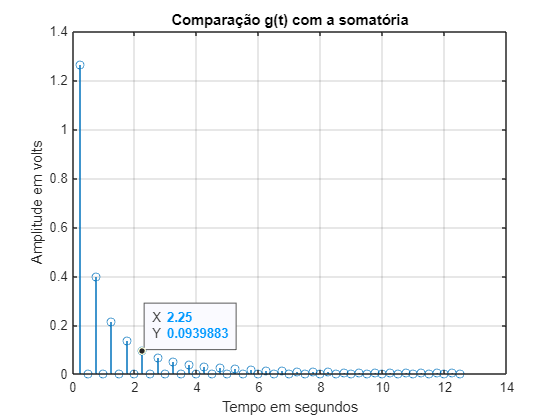


%%% saída do filtro no tempo

ys = ifft(Ys);

figure(11)

stem(n*w0/(2*pi),abs(Ys));
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y

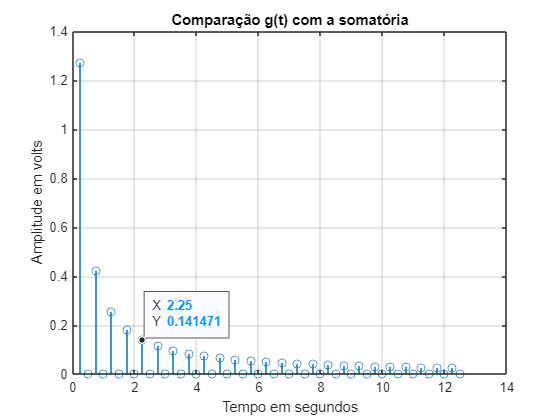

stem(n*w0/(2*pi),f_g);                %%% plota os sinais  - plot(x,y)
grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y

### Passa alta

stem(n*w0/(2*pi),sqrt(abs(an_num).^2 + abs(bn_num).^2),'LineWidth',2);         %%% plota o espectro de an
grid;                                                %%% cria um grid
title('Espectro de a_n');                            %%% título do gráfico
xlabel('Frequência em Hz');                          %%% Eixo x
ylabel('Amplitude em volts - módulo');               %%% Eixo y
%%% Aplicando um filtro


%%% Determinando o filtro

Gw = @(w,wc)  j*w./(j*w + wc);

fc = 2    ;                  %%% frequência de corte
wc = 2*pi*fc;                 %%% frequência de corte em rd/s
frequencia = 0.25*[1:1:N_harmonicas];
w  = 2*pi*frequencia;         %%% vetor de frequências

%%% determinando o ganho do filtro

ganho = Gw(w,wc)
f_g = sqrt(abs(an_num).^2 + abs(bn_num).^2)

ganho =    0.0154 + 0.1231i   0.0588 + 0.2353i   0.1233 + 0.3288i   0.2000 + 0.4000i   0.2809 + 0.4494i   0.3600 + 0.4800i   0.4336 + 0.4956i   0.5000 + 0.5000i   0.5586 + 0.4966i   0.6098 + 0.4878i   0.6541 + 0.4757i   0.6923 + 0.4615i   0.7253 + 0.4464i   0.7538 + 0.4308i   0.7785 + 0.4152i   0.8000 + 0.4000i   0.8187 + 0.3853i   0.8351 + 0.3711i   0.8494 + 0.3576i   0.8621 + 0.3448i   0.8733 + 0.3327i   0.8832 + 0.3212i   0.8921 + 0.3103i   0.9000 + 0.3000i   0.9071 + 0.2903i   0.9135 + 0.2811i   0.9193 + 0.2724i   0.9245 + 0.2642i   0.9293 + 0.2564i   0.9336 + 0.2490i   0.9376 + 0.2420i   0.9412 + 0.2353i   0.9445 + 0.2290i   0.9475 + 0.2230i   0.9503 + 0.2172i   0.9529 + 0.2118i   0.9553 + 0.2066i   0.9576 + 0.2016i   0.9596 + 0.1968i   0.9615 + 0.1923i   0.9633 + 0.1880i   0.9650 + 0.1838i   0.9665 + 0.1798i   0.9680 + 0.1760i   0.9694 + 0.1723i   0.9706 + 0.1688i   0.9718 + 0.1654i   0.9730 + 0.1622i   0.9740 + 0.1590i   0.9750 + 0.1560i


f_g =     1.2732    0.0000    0.4244    0.0000    0.2546    0.0000    0.1819    0.0000    0.1415    0.0000    0.1157    0.0000    0.0979    0.0000    0.0849    0.0000    0.0749    0.0000    0.0670    0.0000    0.0606    0.0000    0.0554    0.0000    0.0509    0.0000    0.0472    0.0000    0.0439    0.0000    0.0411    0.0000    0.0386    0.0000    0.0364    0.0000    0.0344    0.0000    0.0326    0.0000    0.0311    0.0000    0.0296    0.0000    0.0283    0.0000    0.0271    0.0000    0.0260    0.0000


%%% saída do filtro em frequência
Ys = f_g.*ganho


Ys =    0.0196 + 0.1567i   0.0000 + 0.0000i   0.0523 + 0.1395i   0.0000 + 0.0000i   0.0715 + 0.1144i   0.0000 + 0.0000i   0.0789 + 0.0901i   0.0000 + 0.0000i   0.0790 + 0.0702i   0.0000 + 0.0000i   0.0757 + 0.0551i   0.0000 + 0.0000i   0.0710 + 0.0437i   0.0000 + 0.0000i   0.0661 + 0.0352i   0.0000 + 0.0000i   0.0613 + 0.0289i   0.0000 + 0.0000i   0.0569 + 0.0240i   0.0000 + 0.0000i   0.0529 + 0.0202i   0.0000 + 0.0000i   0.0494 + 0.0172i   0.0000 + 0.0000i   0.0462 + 0.0148i   0.0000 + 0.0000i   0.0434 + 0.0128i   0.0000 + 0.0000i   0.0408 + 0.0113i   0.0000 + 0.0000i   0.0385 + 0.0099i   0.0000 + 0.0000i   0.0364 + 0.0088i   0.0000 + 0.0000i   0.0346 + 0.0079i   0.0000 + 0.0000i   0.0329 + 0.0071i   0.0000 + 0.0000i   0.0313 + 0.0064i   0.0000 + 0.0000i   0.0299 + 0.0058i   0.0000 + 0.0000i   0.0286 + 0.0053i   0.0000 + 0.0000i   0.0274 + 0.0049i   0.0000 + 0.0000i   0.0263 + 0.0045i   0.0000 + 0.0000i   0.0253 + 0.0041i   0.0000 + 0.0000i


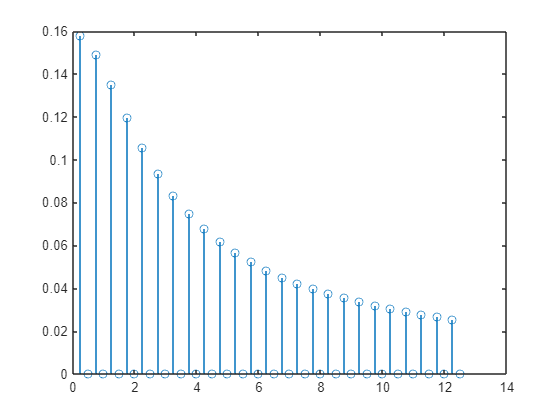

%%% saída do filtro no tempo

ys = ifft(Ys);

figure(11)

stem(n*w0/(2*pi),abs(Ys));
stem(n*w0/(2*pi),f_g);                %%% plota os sinais  - plot(x,y)

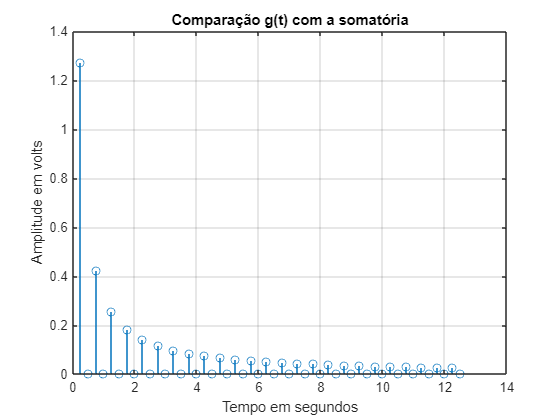

grid;                                                %%% cria um grid
title('Comparação g(t) com a somatória');            %%% título do gráfico
xlabel('Tempo em segundos');                         %%% Eixo x
ylabel('Amplitude em volts');                        %%% Eixo y